# Computing the Pake pattern of a dipolar signal

#### Author: Luis Fabregas

A very basic example for displaying the frequency-domain Pake pattern (spectrum) of a given dipolar signal.

## Generate a dipolar signal

Let's start by simulating a dipolar signal with some background and noise.

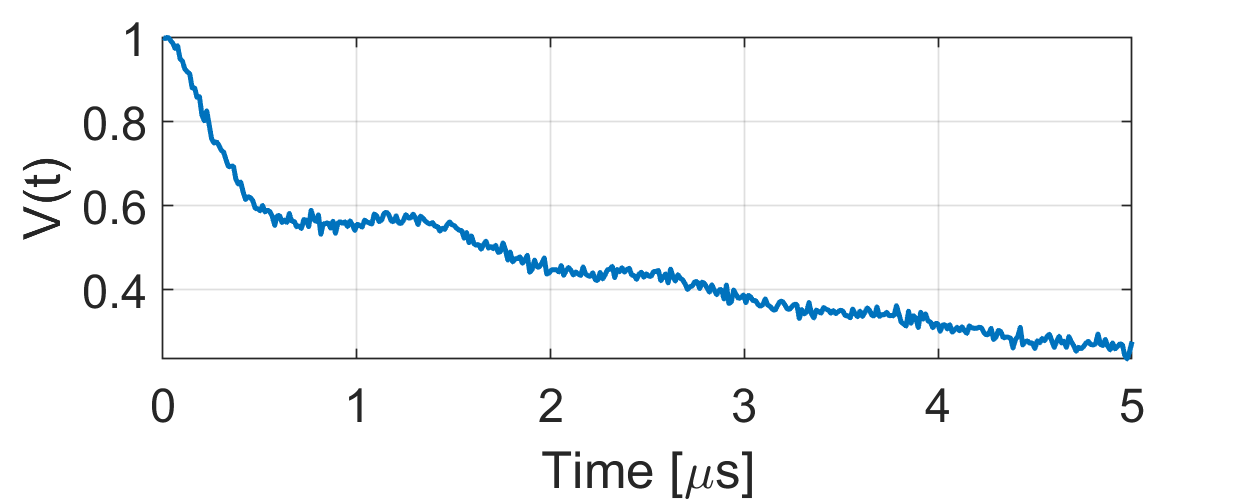

%Prepare components
t = linspace(0,5,400);
r = time2dist(t);
P = rd_twogaussian(r,[3.5 0.3 4 0.2 0.2]);
B = td_exp(t,0.2);
V = dipolarsignal(t,r,P,'moddepth',0.3,'background',B,'noiselevel',0.01);

%Plot
figure('position',[0 0 500 200])
plot(t,V,'Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('Time [\mus]'),ylabel('V(t)')

## Prepare the signal

Since experimental dipolar signals contain the background, this must be fitted removed prior to Fourier transform.

First we proceed to fit the background function using some time-domain parametric model. In this example we will use a stretched exponential function (`td_strexp`). Using the `fitbackground` function we obtain the fitted background as well as the fitted modulation depth.

%Fit the background function
[B,lambda] = fitbackground(V,t,@td_exp); 

Now we can use these fitted variables to isolate the dipolar evolution function from the primary data. Removal of the background via division leads to a noise increase at later times and thus to an approximation `Dcorr` of the real dipolar evolution function.

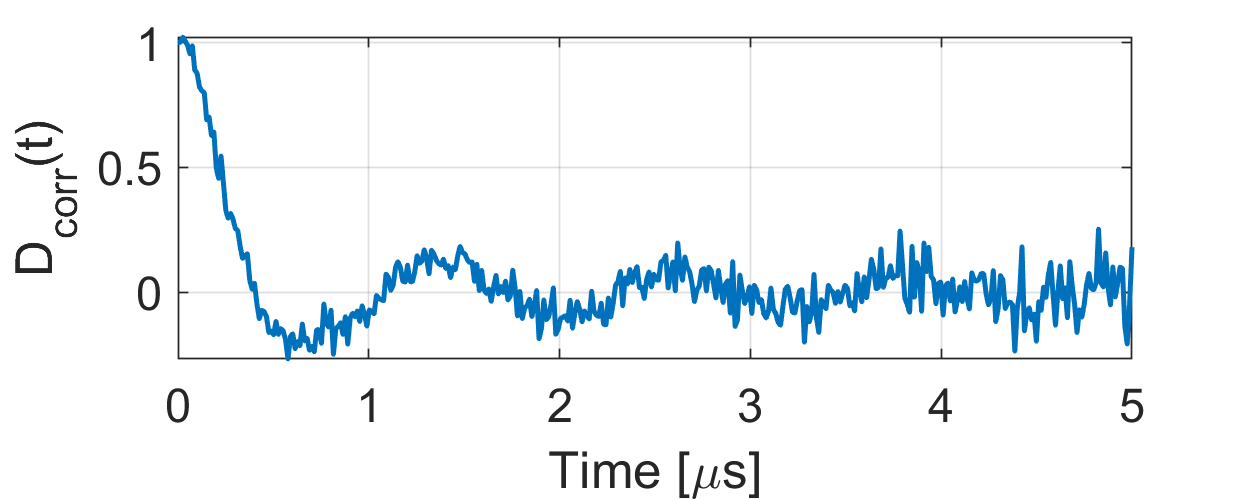

%"Correct" for the background and modulation depth
Dcorr = (V./B - (1 - lambda))/lambda;

figure('position',[0 0 500 200])
plot(t,Dcorr,'Linewidth',1.5)
set(gca,'fontsize',14)
axis tight, grid on
xlabel('Time [\mus]'),ylabel('D_{corr}(t)')

## Generating the Pake pattern

Now that the signal has the appropiate structure for Fourier transform it, we can call the `fftspec` function to obtained the Pake pattern.

%Compute spectrum
[nu,pake] = fftspec(t,Dcorr);

In order to avoid truncation ripples in the Fourier spectrum and at the same time to compensate for the increase of noise, we recommend the use of apodization using the appropiate option in `fftspec`.

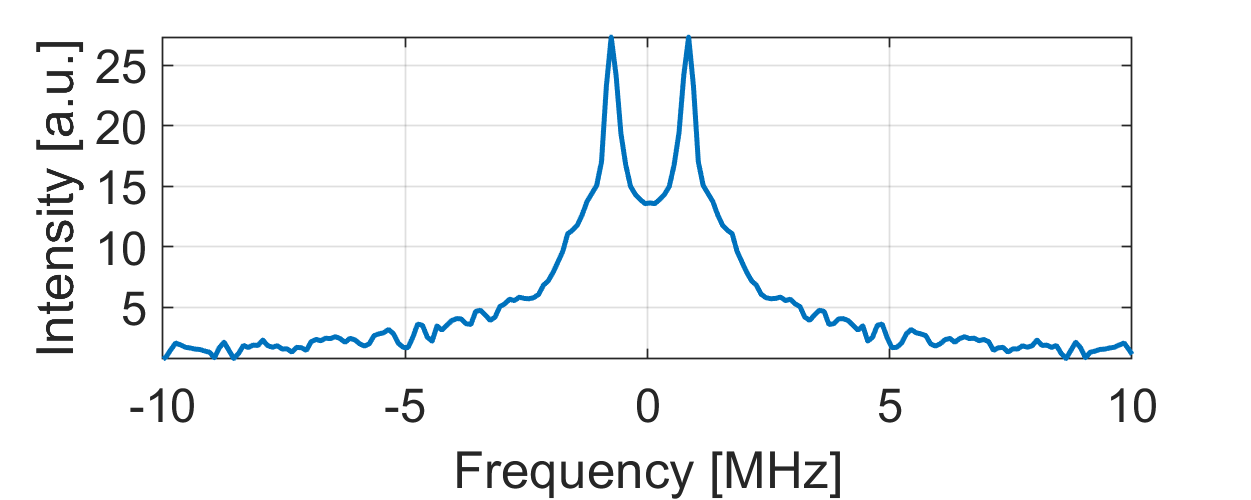

%Compute spectrum with apodization
[nu,pake] = fftspec(t,Dcorr,'Apodization',true);

%Plot results
figure('position',[0 0 500 200])
plot(nu,pake,'Linewidth',1.5)
axis tight, grid on
set(gca,'xlim',[-10 10],'fontsize',14)
xlabel('Frequency [MHz]'),ylabel('Intensity [a.u.]')

We do not need to worry about the zero-filling since `fftspec` takes care of setting it to twice the amount of points in the signal, to preserve all information. Adding more points will artificially increase the resolution of the Pake pattern. The improvement will only be visual as no further information can be gained from additional zero-filling.